Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Orbit correction in a ring (Section 8.5.1)

Volker Ziemann, 211129, CC-BY-SA-4.0

In this example, we illustrate correcting the horizontal orbit in a ring made of eighteen FODO cells with one corrector magnet and one beam position monitor (BPM) in each cell.

We add the support functions for the 4D beam optics calculations and define the FODO cell that has a phase advance of close to $90^o$ in the horizontal plane and $60^o$ in the vertical plane.Then the focal lengths of the thin-lens quadrupoles were slightly changed to give overall tunes of 4.27 and 3.38 for the full ring with 18 equal cells. Note also that we introduced two new element codes: 200 to indicate a corrector magnet and 300 to indicate a BPM.

clear 
addpath ./4D
fodo=[
  1,	25,	0.1,	0;
  2,	 1,	0,	  4.357;    % QF
  200, 1, 0,    0;        % Corrector
  300, 1, 0,    0;        % BPM
  1,	15,	0.1,	0;
  4,	20,	0.1,	1;        % Dipole
  1,	15,	0.1,	0;
  2,	 1,	0,	 -4.4542;   % QD
  1,	25,	0.1,	0];
beamline=repmat(fodo,18,1);

In order to verify that the beta functions and the tunes are the desired ones we calculate the transfer matrices `Racc` and from those the tunes, the periodic sigma matrix with the beta functions sigma0, and then plot the beta functions.

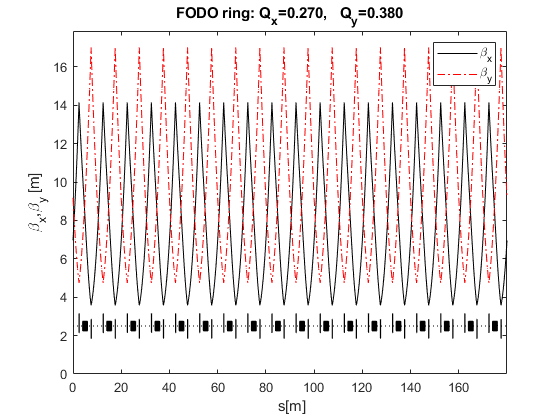

[Racc,spos,nmat,nlines]=calcmat(beamline); Rend=Racc(:,:,end); 
Q=tunes(Rend);
sigma0=periodic_beammatrix(Rend,1,1);
plot_betas(beamline,sigma0);
legend('AutoUpdate','off')  % cosmetic, prevent extra entry in legend
drawmag(beamline,2,1)
title(['FODO ring: Q_x=',num2str(Q(1),'%5.3f'),',   Q_y=',num2str(Q(2),'%5.3f')])

Before simulating the ring, we need to prepare arrays that contain the positions of the correctors, the BPM, and the quadrupoles. To do so we loop over all elements and segments in the beamline, increment counters for each device found; `nquad` for the quadrupoles, `nbpm` for the BPM, and` ncor` for the correctors. At the same time we record their position` ic` in the beam line; in `quadpos()` for the quadrupoles, in `corpos()` for the correctors, and in `bpmpos()` for the BPM . As a convenience, we also record the focal lengths of the found quadrupoles in `quadf()`.

nquad=0; quadpos=zeros(1,36); quadf=quadpos;
nbpm=0; bpmpos=zeros(1,18);
ncor=0; corpos=zeros(1,18);
ic=1;                        
for line=1:nlines            
  for seg=1:beamline(line,2) 
     ic=ic+1;
     switch beamline(line,1)
       case 2    % thin quadrupole
         nquad=nquad+1;
         quadpos(nquad)=ic;
         quadf(nquad)=beamline(line,4);
       case 200  % corrector
         ncor=ncor+1;
         corpos(ncor)=ic;
       case 300  % bpm
         nbpm=nbpm+1;
         bpmpos(nbpm)=ic;
     end
  end
end

Now that  we know the positions  of the correctors and the BPM, we can calculate the response matrix `Cx` in the horizontal plane in a netsed loop over all BPM and over all correctors and for each combination calculating the 4x4 response matrix `C` with  the function `CC()`, which is defined in the Appendix.

Cx=zeros(nbpm,ncor); 
for ibpm=1:nbpm
  for icor=1:ncor
    C=CC(bpmpos(ibpm),corpos(icor),Racc);
    Cx(ibpm,icor)=C(1,2);
  end
end

Likewise we determine the BPM-quadrupole response matrix, which relates a transverse quadrupole displacement $d_x$ to the change of the beam position on a BPM. As for the BPM-corrector response matrix before, we the calcluate 4x4 response matrix `C` with  the function `CC()` and copy its 12-element into the appropriate place in the matrix `Cqx()`. We then divide by the focal length $f$ of the respective quadrupole, because the kick $\theta$ that a displaced quadrupole gives to the beam is $\theta=d_x/f$. 

Cqx=zeros(nbpm,nquad);
for ibpm=1:nbpm
  for iquad=1:nquad
    C=CC(bpmpos(ibpm),quadpos(iquad),Racc);
    Cqx(ibpm,iquad)=C(1,2)/quadf(iquad);
  end
end

We immediately use `Cqx` to calculate effect of displaced quadrupoles on the position recorded on the BPM. We therefore randomly displace the quadrupoles by `dx`, sampled from a uniform distribution in the range $\pm0.5$mm and loop over the BPM; for each BPM we sum the contributions from all quadrupoles to the reading of the BPM.  After the loops complete, we plot `bpmx()` in a bargraph to simulate the typical display of beam positions found in accelerator control rooms. 

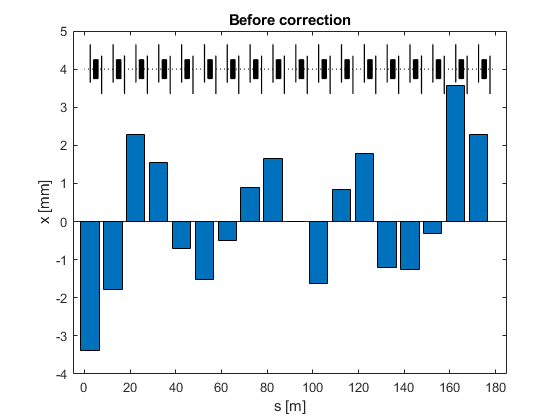

dx=1e-3*(rand(1,nquad)-0.5); % quad displacement
bpmx=zeros(1,nbpm);
for ibpm=1:nbpm
  for iquad=1:nquad
    bpmx(ibpm)=bpmx(ibpm)+Cqx(ibpm,iquad)*dx(iquad);
  end
end
figure; bar(spos(bpmpos),1e3*bpmx); drawmag(beamline,3.5,1);
xlim([-5,spos(end)+5]); xlabel('s [m]'); ylabel('x [mm]');
title('Before correction')

In the next step we use the BPM readings to calculate the corrector setting, based on inverting Equation 8.53, that  is required to zero the BPM readings.

% theta=-inv(Cx)*bpmx';   % old style, less robust 
theta=-Cx\bpmx';    % correction by inverting eq. 8.53

Next, we introduce the possibility to simulate badly calibrated correctors by giving all correctors a scale factor `corscale`. If it is less than unity, say 0.9, all corrector power supplies only produce 90% of the requested current.

corscale=1  % Slider for global corrector calibration error

corscale = 1

We can also select a single bad corrector `badcor` and give it an individual scale error by setting `badcorscale` to a value different from unity. By chosing badcorscale=-1 we can simulate a power supply with flipped polarity.

badcor=2;  % second corrector is bad
badcorscale=1% Slider for scale error of the bad corrector

badcorscale = 1

if badcor>0
  theta(badcor)=badcorscale*theta(badcor); % single corrector with wrong calibration
end 

Finally, we add the effect of the corrector magnets with non-zero excitation to the BPM reading and display the resulting orbit.

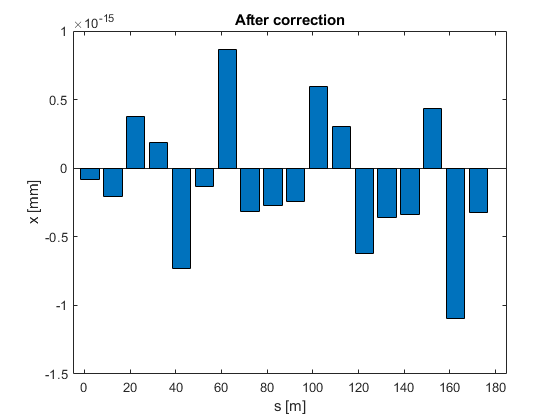

for ibpm=1:nbpm         % add corrections to bpm
  for icor=1:ncor
    bpmx(ibpm)=bpmx(ibpm)+corscale*Cx(ibpm,icor)*theta(icor);
  end
end
figure; bar(spos(bpmpos),1e3*bpmx); 
xlim([-5,spos(end)+5]); xlabel('s [m]'); ylabel('x [mm]');
title('After correction')

Note that without any errors the orbit correction is perfect and the resulting BPM readings ar zero to machine precision.

Now it's time to play with the scale errors of the corrector magnets to simulate how much badly calibrated steering magnets affect the orbit correction. You might also want to add code to simulate bad BPMs.

## Appendix

#### CC()

The function `CC()` receives the positions of the BPM and corrector in the beam line sequence and the transfer matrices `Racc` as input and returns the 4x4 response matrix from Equation 8.28 as `out`. Inside the function, we have to separately treat the cases, where the index of the BPM is larger than that of the corrector, or vice-versa.

function out=CC(ipos,jpos,Racc)
Rjj=Racc(:,:,jpos)*Racc(:,:,end)*inv(Racc(:,:,jpos));
if ipos > jpos
  Rij=Racc(:,:,ipos)*inv(Racc(:,:,jpos));
else
  Rij=Racc(:,:,ipos)*Racc(:,:,end)*inv(Racc(:,:,jpos));
end
out=Rij*(inv(eye(4)-Rjj));   % eq. 8.28
end

#### calcmat()

We have amended the function `calcmat()` for this program to handle the correctors with code 200 and the BPM with code 300 to prevent many `unsupported code` messages. The rest of the function is unchanged.

function [Racc,spos,nmat,nlines]=calcmat(beamline)
ndim=size(DD(1),1);  
nlines=size(beamline,1);      % number of lines in beamline
nmat=sum(beamline(:,2))+1;    % sum over repeat-count in column 2
Racc=zeros(ndim,ndim,nmat);   % matrices from start to element-end
Racc(:,:,1)=eye(ndim);        % initialize first with unit matrix
spos=zeros(nmat,1);           % longitudinal position
ic=1;                         % element counter
for line=1:nlines             % loop over input elements
  for seg=1:beamline(line,2)  % loop over repeat-count 
     ic=ic+1;                 % next element          
     Rcurr=eye(4);            % matrix in next element
     switch beamline(line,1)  
       case 1   % drift
         Rcurr=DD(beamline(line,3));
       case 2   % thin quadrupole
         Rcurr=Q(beamline(line,4)); 
       case 4   % sector dipole
         phi=beamline(line,4)*pi/180;  % convert to radians
         rho=beamline(line,3)/phi;
         Rcurr=SB(beamline(line,3),rho);
       case 5   % thick quadrupole
         Rcurr=QQ(beamline(line,3),beamline(line,4));           
       case 20  % coordinate roll
         Rcurr=ROLL(beamline(line,4));
       case 200 % corrector
         Rcurr=eye(4);
       case 300 % BPM
         Rcurr=eye(4);
       otherwise
         disp('unsupported code')
     end		  
     Racc(:,:,ic)=Rcurr*Racc(:,:,ic-1);    % concatenate 
     spos(ic)=spos(ic-1)+beamline(line,3); % position of element   
  end
end
end